**Propagación a través de una rejilla de forma cosenoidal **

Establecimiento de parámetros físicos 

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de representación
Nx = 1024;
Ny = 1024;

% Condiciones de Muestreo
dx =0.5*um;
dy =0.5*um;

lambda = 650*nm;

Creación de la rejilla por medio de la función rejilla.m

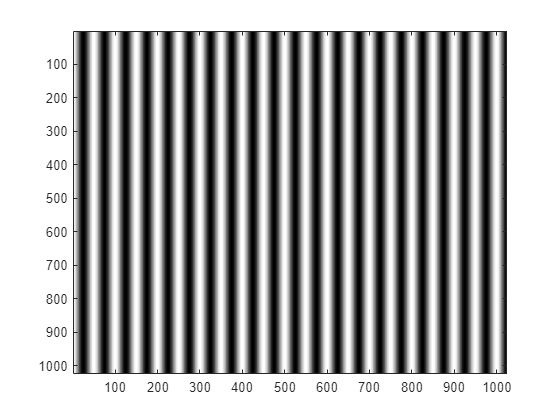

% Condiciones de la rendija
m = 1;
L = 50*dx;
transmitancia = rejilla(Nx,Ny,dx,dy,m,L);
imagesc(transmitancia)
colormap('gray')

Se observa intensidad a lo largo del eje x 

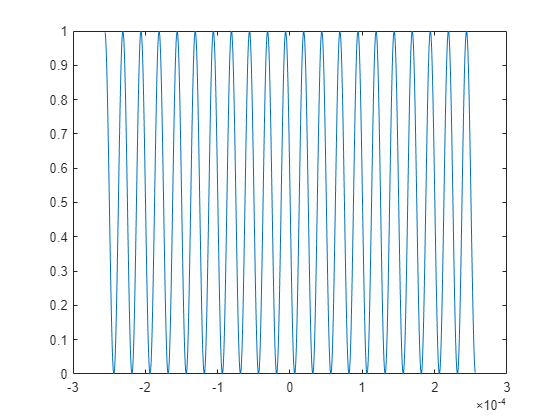

% Perfil de intensidad a lo largo del eje x de la rejilla de difraccion
I = transmitancia(round(Ny/2),1:end)';
x0 = 1-Ny/2:Ny/2;
x0 = x0*dx;

% Se grafica
plot(x0,I);

Se propagará distancias equivalente a enteros de la propagación propuesta

% Distancia de propagación
nImpar = 1;
zImpar = nImpar*((L^2)/lambda);

nPar = 2;
zPar = nPar*((L^2)/lambda);

Propagación con numero entero impar

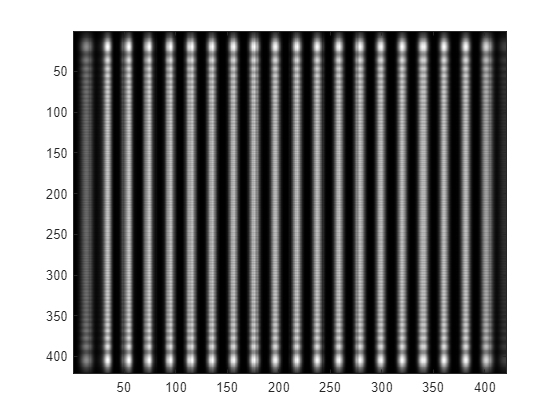

transmitanciaPropOdd = transformadaFresnel(transmitancia,dx,dy,zImpar,lambda,dft=false,zoom = true);
intensidadOdd = abs(transmitanciaPropOdd).^2;
imagesc(intensidadOdd)

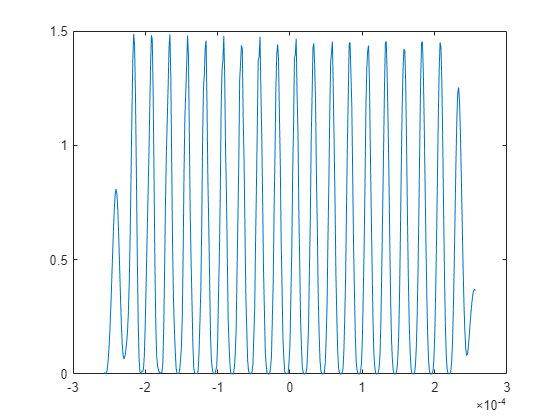

% Perfil de intensidad a lo largo del eje x de la propagada
[hI, ~] = size(intensidadOdd);
IpropagadaOdd = intensidadOdd(round(hI/2),1:end)';
x = 1-round(hI/2):round(hI/2)-1;
x = x*(lambda*zImpar/(Nx*dx)); % Condicion de muestreo en el plano de observación ya que se utiliza
                               % Transformada de fresnel

% Se grafica
plot(x,IpropagadaOdd*10^37)

Ahora se grafican los perfiles de intensidad, se puede observar un corrimiento de fase de una respecto a la otra de aproximadamente pi/2

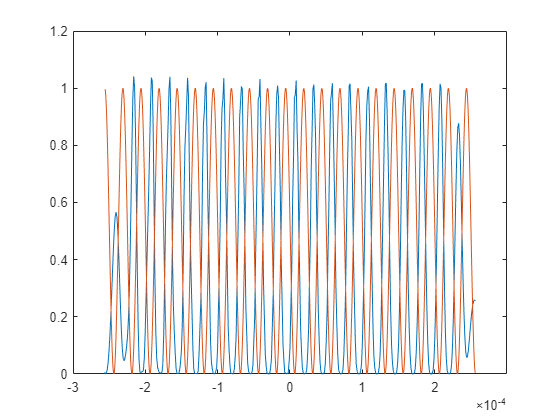

% Comparación de las intensidades 
plot(x,IpropagadaOdd*10^37*0.7)
hold on
plot(x0,I)
xlim([-3E-4 3E-4])
hold off

Propagación con numero entero par

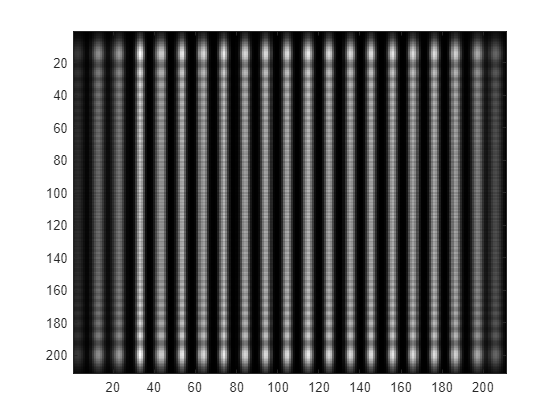

transmitanciaPropEven = transformadaFresnel(transmitancia,dx,dy,zPar,lambda,dft=false,zoom = true);
intensidadEven = abs(transmitanciaPropEven).^2;
imagesc(intensidadEven)

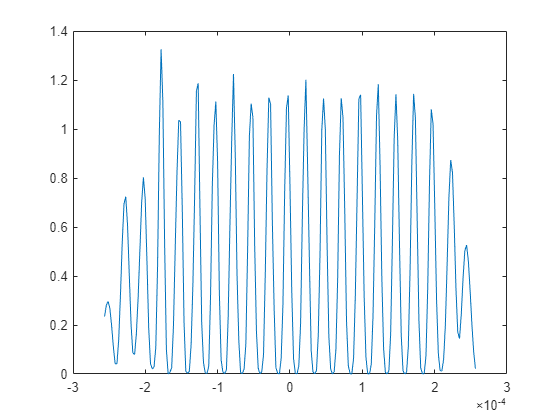

% Perfil de intensidad a lo largo del eje x de la propagada
[hI, wI] = size(intensidadEven);
IpropagadaEven = intensidadEven(round(hI/2),1:end)';
x = 1-round(hI/2):round(hI/2)-1;
x = x*(lambda*zPar/(Nx*dx)); % Condicion de muestreo en el plano de observación ya que se utiliza
                               % Transformada de fresnel

% Se grafica
plot(x,IpropagadaEven*10^36*0.5)

Ahora se grafican los perfiles de intensidad, se puede observar un corrimiento de fase de una respecto a la otra de aproximadamente pi o 0

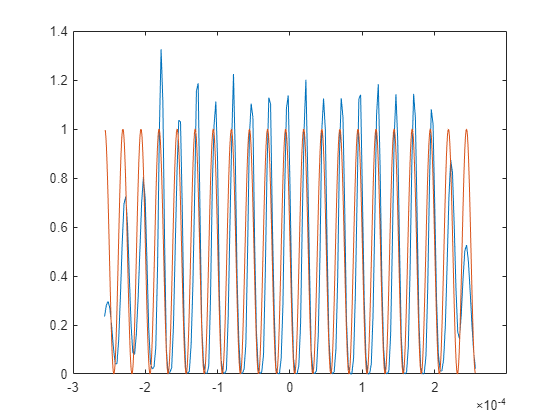

% Comparación de las intensidades 
plot(x,IpropagadaEven*10^36*0.5)
hold on
plot(x0,I)
xlim([-3E-4 3E-4])
hold off